# **FINAL PROJECT PROPOSAL**

# **   SYS 6014 **

# **JAMIE QUINTANA**

### **TABLE OF CONTENTS**

- INTRODUCTION

- DECISION PROBLEM

- PREDICTIVE MODEL

- PRIOR BELIEFS

- DECISION MATRIX

- RESULTS* (when finalized)*

- CONCLUSION* (when finalized)*

- REFERENCES 

***Key Words:*** Bitcoins, binomial distribution, Bayesian analysis, decision making, classification, machine learning, regression

***Reproducable Research:*** to create report, use Matlab 2019b or higher with all toolboxes, run live notebook 03-05-2020_SYS-6014_Project_Proposal_Final.mlx. Prerequisite file needed 03-05-2020_BTC_Data.csv. 

### **Introduction**

     **U**se of the word “bitcoin” was virtually non-existent until ~2008.  The word first appeared in a white paper titled Bitcoin: A Peer-to-Peer Electronic Cash System credited to Satoshi Nakamotox on October 31st, 2008. The paper discussed a new approach to use a peer-to-peer system that would allow decentralized online cash exchanges without a third-party financial institution. Meaning, individuals could use this new type of crypto currency to send or receive bitcoins to other individuals directly. The proposed solution leveraged existing technologies including use of Digital signatures, as part of the solution, and suggested a new method of using network timestamps transactions, which culminate with a record that cannot be easily changed (Nakamoto, 2008).

The value of bitcoins have changed significantly since 2014. As an example, on Dec 1st, 2014 the bitcoin to dollar equivalency was one bitcoin was worth $370 U.S Dollars. Today, the current exchange rate of one bitcoin equals $9,922; so, that same $370 will buy you only a fraction of a bitcoin. Since the value of bitcoins change based on many factors, the type of problem being addressed in this paper is focused on tactical purchases. That is, buying bitcoins to trade or use on the same day or at most the next day. To cite an example, if a person buys $500 of bitcoins on Feb 19th 2020, and then wants to purchase something the next day, that original $500 in bitcoins is worth only $471 dollars on Feb 20th, 2020; hence, a ~$29 loss in value. For this reason, this project topic is concerned with crypto currencies and when might be the best or optimal time to buy Bitcoins. That is, ideally, a decision maker would endeavor to buy currency on a day the price will likely go up vice down. Unlike stocks, crypto currency prices change based on various factors and is tracked every day. The focus here is to take the historical data (which is readily available) draw the line say at the end of Dec 31, 2019, and calculate probabilities for each day – Monday-Sunday to determine if one or more days are preferred to buy than another (calculate utility/loss functions for each, which will drive the decision to buy (or not). Basically – the price can go up or down (i.e. binary) from one day to the next **p =.5**; however, the actual probabilities may be (and most likely are) different depending on the overall data set (summed) or calculated for each day, each month, or determined by some prediction model. 

To establish a baseline, the binomial distribution can be used to examine the probabilities of events occurring based on some properties of the random variable. In this case, the random variable is the state of the bitcoin price going up or down. Here, the success of the trial occurs when the price goes up (i.e. the desired outcome). The assumptions here are each trial is independent and not influenced by the previous result. The probability density function of the binomial distribution is as follows: 

## 
$$$$ P(A) = \sum P(\{ (d_1,...,d_N) \})  = {{N}\choose{k}  }p^kq^{N-k}$$)
$$


Where ***d*** if the number of days and ***N*** is the number of trials. ***P*** is the probability of success (in this case p = .5) and ***k*** is the desired number of successes. As an example, considering the next 53 days, Bitcoin prices have a 50-50 chance of going up or down. So, if we to determine the probability of randomly guessing the price will go up (i.e. be a success) for 30 of those 53 days, the probability equals:

1 - binocdf(30,53,0.5)

ans = 0.1358

Which means, at 13%, the odds are fairly low that a person using no other tools would have a low success rate at making a decision to buy Bitcoins and getting the desired results. If we assume we can build a prediction model that can increase the probability of success from .5 to say, .66, then the following chart plots out the Cumulative Density Function over those probabilities:

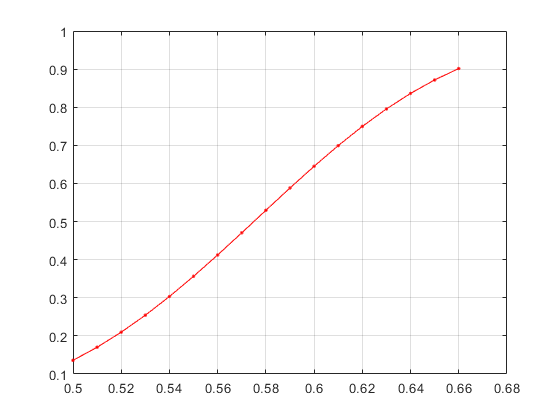

chance = 0.5:0.01:0.66;
y = 1 - binocdf(30,53,chance);
plot(chance,y, 'r.-')
grid on

As shown in the plot, the probability of getting 30 predictions correct increases significantly to 90% when the probabilty of success is increased to .66. So, the goal of this project is to increase the rate of probability to determine the next "success" to some probability > .5.  Even though, this seems promising as an example,  here the success rate is still 30/53 = ~57% accuracy, which is actually not very good taken as a whole. 

### Decision Problem

**        A**s mentioned in the previous section, the decision maker has a menu of options at his or her disposal. The decision-maker's ***action set*** $A$ is a complete itemization of all the options available to the decision-maker, from which the decision-maker selects a unique choice. In this project, we define ${\mathit{\mathbf{a}}}_{\mathit{\mathbf{d}}}$ to be a binary control variable that takes a value of **1** if a decision to buy bitcoins on date **d**, and **0 **otherwise. Let random variable $X$** = **($\left.x_{d,\;} x_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} x_1 \right)$denote the vector of potential probabilities, which the decision maker will encounter and let **a = **($\left.a_{d,\;} a_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} a_1 \right)$ denote the vector of all decisions taken on givens days which consume a given budget ***B***. For this project, the max budget ***B***  is set at **$5,000**. Then $a\cdot x=\sum a_d x_d$  is the realized number of successful purchases (where bitcoin price went up as predicted) per given day.   The goal to maximize in expectation the total number of successful purchase days, which can be expressed as (Small, et al, 2010) :

## $\underset{a}{\textrm{MAX}}$ ***E*** [$a\cdot x$] subject to budget constraint $\sum a_d$ $\le B$

This project creates a scenario where the decision maker has to make ten purchases each **@ $500** of bitcoins within a 30-day period using the decision tools in this project. As a comparison, the results of the maximized decisions using the model's data will be compared against ten "randomized" purchases within the defined 30-day period to compare the performance (i.e. the value) of the model*. *Below is a full list of actions which the decision maker will make... other possible actions can/may be added as the course progresses. 

##   **Actions**  - ***No.  Description ***

------------------------> 1  Do not buy bitcoins 

------------------------> 2  Buy bitcoins without using model data 

------------------------> 3  Buy bitcoins on Mondays 

------------------------> 4  Buy bitcoins on Tuesdays 

------------------------> 5  Buy bitcoins on Wednesdays 

------------------------> 6  Buy bitcoins on Thursdays 

------------------------> 7  Buy bitcoins on Fridays 

------------------------> 8  Buy bitcoins on Saturdays 

------------------------> 9  Buy bitcoins on Sundays 

------------------------> 10  Buy bitcoins based on price prediction forecast (next day prediction: up or down)

### **Prediction Model**

**        S**pecifically tied to action no. 10 as described above, this action requires creating a classification or machine learning models using neural networks, SVMs, etc. that use the data (perhaps even transformed using filters, tools, feature extractors) to forecast or predict outcomes. The core model will use historical data exclusively to predict the next day's price value - and then compare the predicted values over actual values for a period of time - say 53 days to align with the binomial estimation in the first section. The objective here is to create a model "baseline" from which subsequent days can be "added" to the last day to predict the next day's outcome. The models accuracy will be based on actual states of the prices going up or down versus predicted outcomes. In this case, we will examine the random variable  $\Upsilon \;$containing $\gamma$ samples generated by the model. The goal will be to minimize the error components$\in$ based on the following expression:

## $\Upsilon_i =\gamma_0 +\varepsilon_i \;\;,\;\varepsilon_i \sim N\left(o,o_{\gamma }^2 \right)$, i.i.d. ,  $\overset{\textrm{Min}}{\hat{\gamma_0 \;} }$ $\sum_i {\left(\hat{\gamma_o } -\gamma_i \right)}^2$ =  $\sum_i {\left(\hat{\varepsilon_i } \right)}^2$

Once the model parameters have been configured in a way that minimizes the residual errors in the prediction price vector, and binary sequence will be generated to forecast whether next day's price will go up or down when subtracting observed - predicted or predicted - observed. The resulting binary vector (i.e. 01010011100011), will be compared against a key to determine actual model performance; once the highest value of performance is obtained, the model parameters will be locked down, and only subsequent days, one day at a time, will be added to determine the next day's decision (i.e. to buy or not). Both **Type I** and **Type II** errors in the model's prediction vector will be captured and recorded in the results section of this report.

For this project, the state space or sample space is defined *as *Χ. The full set of direct data will be used, but not altered from its original state. Instead, the sample space for each action will be derived (i.e. calculated) from the full set of data as described in the next section. Full data set contains 6 columns of numerical 1898 data points (i.e. from 12/1/2014 to 2/22/2020) with column titles - Open, High, Low, Close, Volume BTC, and Volume USD. This can be considered a data generating process, which takes the form of a statistical model describing the statistical properties of random variables  ${}x_1$,${}x_2$,…,${}x_n$∈ X. So for each Random variable ${}x_i$,~ 263 data points will be parsed (i.e. filtered) from the entire data set for each day of the week. Then, each group of 263 ~ data points will be divided into two groups: first group summing all times the bitcoin price when up, and second for all times the prices went down. Then their associated  $L\left(\theta ,a\right)$'s will be calculated for each day. A quick look at the entire data set reveals that neither price going up or down is a rare occurrence (i.e. 2% over the lifetime of bitcoins). Additionally, since 8/12/2018 the price of bitcoins have not once remained the same from open to close, so for the project, the probability that the price remains the same is left out of the decision model. To account for any future occurrences, the model will treat a no gain or loss day as a success - which makes intuitive sense, because no money was actually lost. 

For this project, the complete *parameter space *$\Theta$ containing all the possible states will be contained within $\Theta =\left\lbrack 0,1\right)$, with set of all possible values of θ and ${}{\sigma }^2$: $\Theta =R\times \left\lbrack 0,\infty \right)$.Although, most of the observed θ's with be roughly in the ~.5 range with the goal of the project that predictive model will obtain $L\left(\theta ,a\right)$'s with $\theta^{\prime } s\;$above the .5 value nearing .6 or .7 if achievable. 

Regarding the unknowns, This project may consider the option of determining the average gain or loss on a particular day of the week to be used as a scale-type factor associated with the "value" of a price going up or down for a given day of the week. Meaning,  unlike the proposed decision matrix further down where all the perceived values are the same for each day of the week, they will be scaled - or adjusted based on the calculated average... I'll assume for now they will not be all the same and some variance will be determined.  The source of data used in this project will be downloaded from here: URL for full data source (updated hourly, daily): [http://www.cryptodatadownload.com/data/coinbase/](http://www.cryptodatadownload.com/data/coinbase/)

The below code, plots, and Matlab output data will be used to create the baseline prediction model as described in the previous sections:

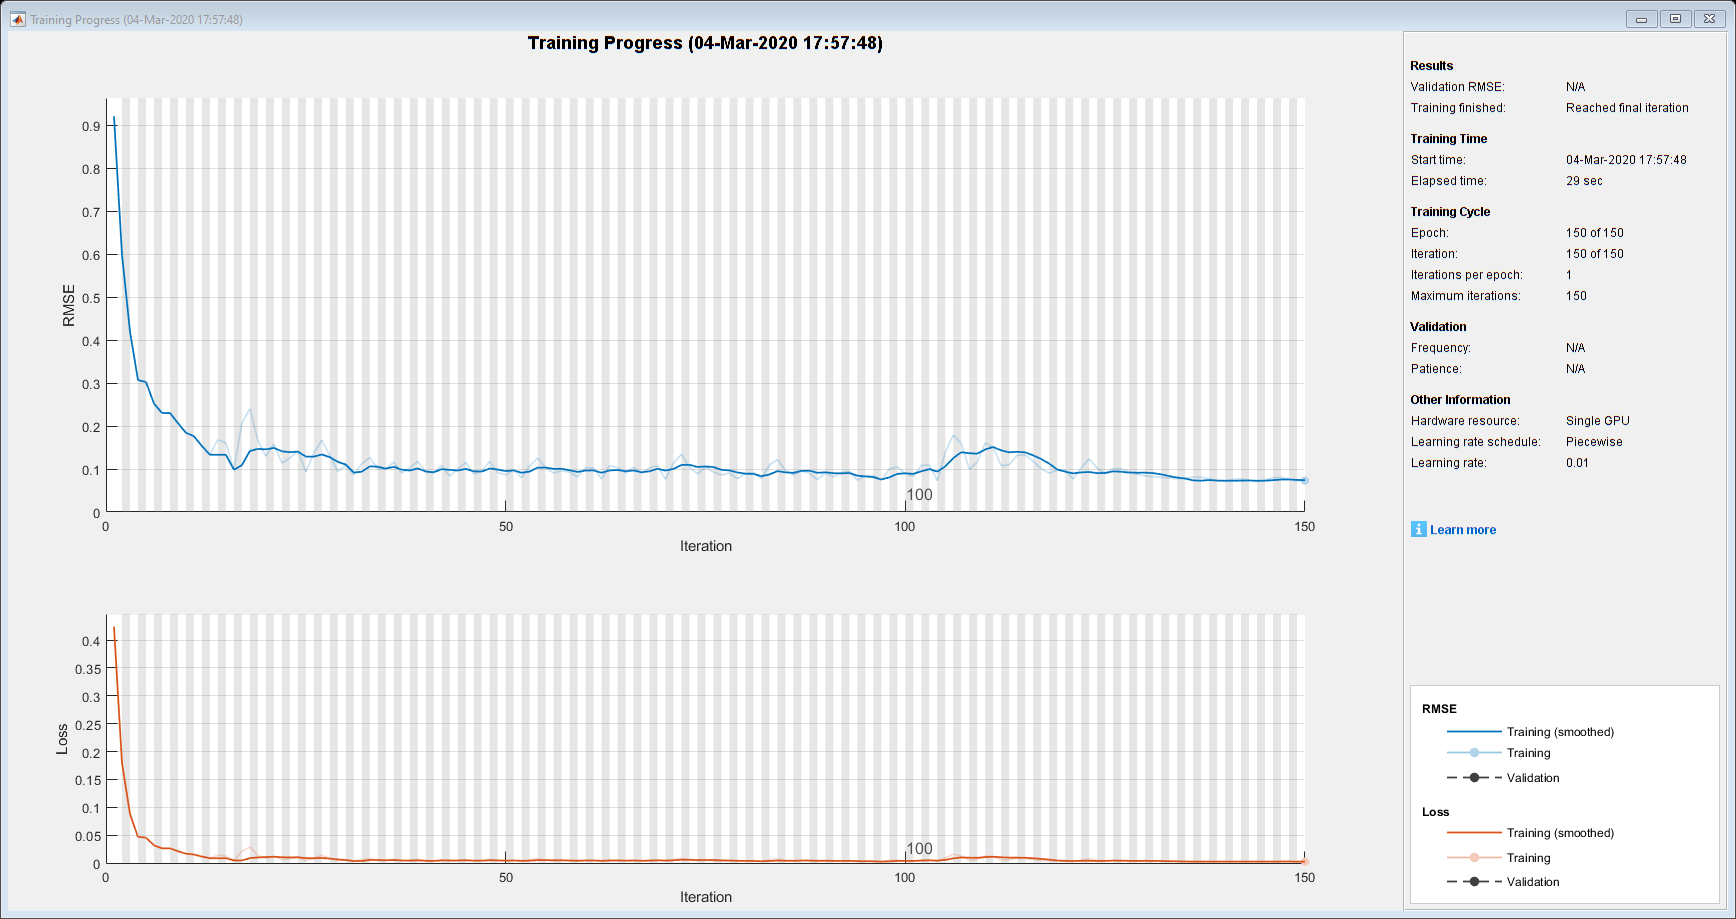

clear all;
close all;
rng(345);
input = csvread('2020-03-05_BTC-data.csv');
data = input;
data = data';
data(1846)=data(1845);
numTimeStepsTrain = floor(0.984*numel(data));
dataTrain = data(1:numTimeStepsTrain+1);
dataTest = data(numTimeStepsTrain+1:end);
mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;
XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);
numFeatures = 1;
numResponses = 1;
numHiddenUnits = 17;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];
options = trainingOptions('adam',...
    'MiniBatchSize',1,...
    'MaxEpochs',150, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.05, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);
net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
3.5006e+03

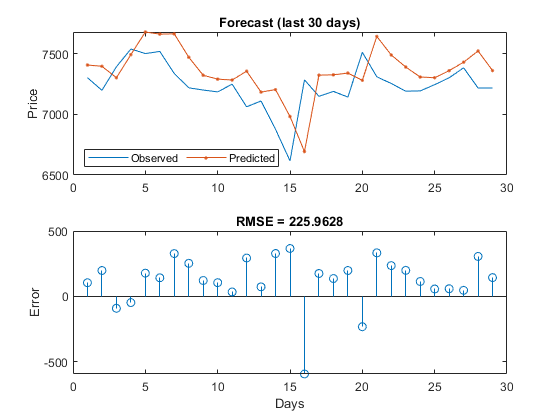


net = resetState(net);
net = predictAndUpdateState(net,XTrain);
YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end
YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2));
figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
%legend(["Observed" "Predicted"])
legend({'Observed','Predicted'},'Location','southwest','NumColumns',2)
ylabel("Price")
title("Forecast (last 30 days)")
subplot(2,1,2)
stem(YPred - YTest)
xlabel("Days")
ylabel("Error")
title("RMSE = " + rmse)

### **Prior Beliefs**

**        T**his section discusses the decision-maker's ***prior beliefs ***$\pi \left(\theta \right)$*. *These beliefs describe the information or beliefs the decision-maker has about the values of the unobserved parameters before collecting data. These beliefs can generally be represented as a probability distribution over the parameter space $\Theta$. I think most people (i.e. decision makers) believe there is no real, consistent, reliable way to determine when is the best time to make a purchase - almost regardless of what it is (assuming whatever stock or asset being purchased is optional and not mandatory). Point in case is the plot below of bitcoin prices from the very start until Dec 31st, 2019. Unlike the random prediction varaible $\Upsilon$, the actual probabilities for the complete set of data - call it prior beliefs or actual beliefs based on real data values, the error component in the below expression virtually disappears (i.e. set $\in \;=\;0\;\;\;\forall \;\varepsilon_i \;$) : 

## $\chi_i =x_0 +\varepsilon_i \;\;,\;\varepsilon_i \sim N\left(o,o_{\gamma }^2 \right)$, i.i.d. ,  $\overset{\textrm{Min}}{\hat{x_0 \;} }$ $\sum_i {\left(\hat{x_o } -x_i \right)}^2$ =  $\sum_i {\left(\hat{\varepsilon_i } \right)}^2$

As seen in the plot below, the price changes from one day to the next seem erratic or stochastic vice deterministic or linear.  A piece-wise linear regression approach to predict the $\beta$ components in the following linear regression expression will be used. 

## $\chi {\;=\;\beta }_o$ + $\beta_1$$\ast$ $x_1$ + $\beta_2$ $\ast$ $x_2$ + $\varepsilon$ 

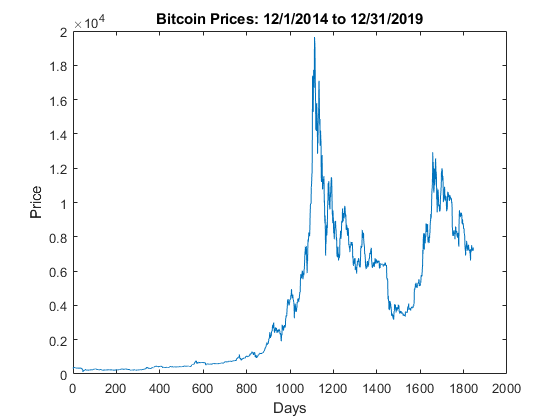

figure
plot(data)
xlabel("Days")
ylabel("Price")
title("Bitcoin Prices: 12/1/2014 to 12/31/2019")

So, in the case of this project, any prior belief that there exists some method or previous way to determine if price will go up or down is off the table. Meaning, project will assume the probability is 50/50 **(p = .5)** one way or another and no external factors or variables outside the data set will be used or referenced. So without trying to quantify the amount of price increases or decreases, the simple answer to the question of "will bit coins go up or down the next day" is binary. That is, yes or no. 

This project will use Bayes Rule, also known as Bayesian Inference (Hoff, 2009), as a way to determine or understand how new information may impact or change one’s previous view about some probability distribution or likelihood of events occurring. The Bayesian method helps by providing the following:

"• parameter estimates with good statistical properties;

 • parsimonious descriptions of observed data;

 • predictions for missing data and forecasts of future data;

 • a computational framework for model estimation, selection and validation" (Hoff, pg.1, 2009).

The following expression describes Bayes Rule, which details the posterior distribution:

###  
$$p\left(\theta \left|y\right.\right)=\frac{p\left(y\left|\theta \right.\right)p\left(\theta \right)}{\int_{\Theta } p\left(y\left|\theta^ˆ \right.\right)p\left(\theta^ˆ \right)d\theta^ˆ }$$


Where $p\left(\theta \right)$ and $p\left(y\left|\theta \right.\right)$represent a the person’s current beliefs and $p\left(\theta^ˆ \right)$ and $p\left(y\left|\theta^ˆ \right.\right)$ represent new information which could alter a person's beliefs (aka posterior beliefs). The posterior probability is the resulting probability that an event will occur once additional information has been gathered, learned, or predicted. Depending on the new information, it could change prior belief by either supporting a claim or providing evidence to the contrary. The prior probability or beliefs in this project will be close to 50/50 or p=.5 in which is the probability of the bitcoin price going up or down will occur. 

The relevant ***payoffs*** that could result from the action. Payoffs will be a function of the selected action **a**, where we le ***u( a , x)*** represent the payoff based on action **a**, and the realized value (or state) of our random variable  ***x***** = **($\left.x_{d,\;} x_{d-1,\ldotp \ldotp \ldotp \ldotp \ldotp \;} x_1 \right)$.  The expression below represents the expected payoff in terms of **U*****( a , ***$\theta$***) ***as a function o***f ***$\theta$ (Small, 2020):

##  $U\left(a,\theta \right)$*** = ***$E\;\left\lbrack u\left(a,\chi \right)\left|\theta \right.\right\rbrack =\;$$\int_{\chi } p\left(x\right)u\left(a,x\right)\textrm{dx}$

As discussed in the previous section, the value associated with making a decsion to buy on a particular day where average prices tend to be higher than other days. The data will dertermine or drive this concept. 

### **Decision Matrix**

**        F**or the proposed model, a decision matrix will be generated to help drive the optimal decision. Different values associated with each action selection could be based on three different risk profiles (i.e. *Risk Neutral, Risk Averse, and Risk Seeking*). Table below is notionally Risk Neutral. Additional tables can be generated based on actual amount of investment i.e. values adjusted non linearly as quantity of the bitcoin purchase increases - perhaps, $100, $1000, and $10000 options. The below chart is one of the project deliverables. 

Actions = ["Do not buy bitcoins", "Buy bitcoins without model data","Buy bitcoins on Mondays","Buy bitcoins on Tuesdays","Buy bitcoins on Wednesdays","Buy bitcoins on Thursdays","Buy bitcoins on Fridays","Buy bitcoins on Saturdays","Buy bitcoins on Sundays","Buy bitcoins using predictive models"];
PriceUp = [.5,.5,.43,.47,.53,.49,.56,.51,.42,.6];
PriceDown = [.5,.5,.57,.53,.47,.51,.44,.49,.58,.4];
ValueSuccess = [3,10,10,10,10,10,10,10,10,10];
ValueFailure = [0,-10,-10,-10,-10,-10,-10,-10,-10,-10];
Payoff = [1.5,0,-1.4,-.6,.6,-.2,1.2,.2,-1.6,2];
Actions = Actions';PriceUp = PriceUp';PriceDown = PriceDown'; ValueSuccess = ValueSuccess';ValueFailure = ValueFailure';Payoff = Payoff';
table1 = table(Actions,PriceUp,PriceDown,ValueSuccess, ValueFailure, Payoff);
table1

table1 = 10×6 table
                   Actions                    PriceUp    PriceDown    ValueSuccess    ValueFailure    Payoff
    ______________________________________    _______    _________    ____________    ____________    ______

    "Do not buy bitcoins"                       0.5         0.5             3               0           1.5 
    "Buy bitcoins without model data"           0.5         0.5            10             -10             0 
    "Buy bitcoins on Mondays"                  0.43        0.57            10             -10          -1.4 
    "Buy bitcoins on Tuesdays"                 0.47        0.53            10             -10          -0.6 
    "Buy bitcoins on Wednesdays"               0.53        0.47            10             -10           0.6 
    "Buy bit

**Note:** the $\pi \left(\theta \right)$ for actions 1 and 2 is assumed. and the ${\left(\theta \right)}^{\prime } s\;$for actions 3 through 10 are synthetic or simulated (placeholders for the real values to be calculated). Also, instead a a negative perpective of using a loss function, project will use a positive payoff perspective - seeking higher values being the best choice to drive the decision.   

### Results (future)

### Conclusion (future)

### References

Berger, James O. Statistical Decision Theory and Bayesian Analysis, 2nd ed. Springer, 1993. ISBN: 978-0387960982.

Hoff, Peter D. A First Course in Bayesian Statistical Methods. Springer, 2009. ISBN: 978-0387922997.

Nakamoto, Satoshi (31 October 2008). "Bitcoin: A Peer-to-Peer Electronic Cash System" (PDF). bitcoin.org. 

Small, A. III (2020, February 3). 2020-02-03_Decision_Analyis_slides. Retrieved February 29, 2020, from [https://github.com/UVA-Engineering-Decision-Analysis/course-materials/blob/master/slides/2020-02-03_Decision_Analyis_slides.pdf](https://github.com/UVA-Engineering-Decision-Analysis/course-materials/blob/master/slides/2020-02-03_Decision_Analyis_slides.pdf)

Small, A, III, Stefik, B, Jason, Verlinde, Johannes, Johnson, C, Nathaniel. "The Cloud Hunter’s Problem: An Automated Decision Algorithm to Improve the Productivity of Scientific Data Collection in Stochastic Environments." MONTHLY WEATHER REVIEW vol 139, pp. 2276-2289, Dec. 2010

Vigna, Paul; Casey, Michael J. (January 2015). *The Age of Cryptocurrency: How Bitcoin and Digital Money Are Challenging the Global Economic Order* (1 ed.). New York: St. Martin's Press. [ISBN](https://en.wikipedia.org/wiki/International_Standard_Book_Number) [978-1-250-06563-6](https://en.wikipedia.org/wiki/Special:BookSources/978-1-250-06563-6).